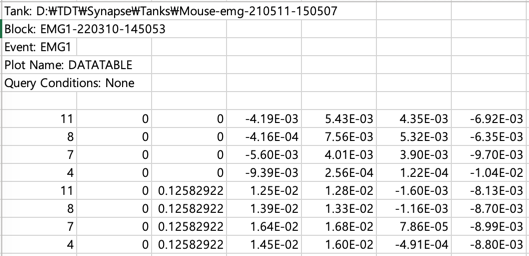

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴

This file has 4 channels: 

ans =      4     7     8    11


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 2.976643초입니다.


%                            organoid, channel, month 


#### 1. 특정 시간 구간의 signal만 사용하기

emg = reader.readSingleChannelFromFile(1, 8, 1);

sampling rate = 1017.250000Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
